# Assignment 1 - Conditioning and sensitivity

## Examples and demonstration

### Converting to single precision

Matlab stores numbers by default in 64-bit double precision floating-point numbers.  To demonstrate the beahvior of floating-point errors, we convert numbers to single-precision to do computations and then compare the result to the double-precision computation (which we treat as the "true" solution).

#### Demonstrating cancellation error

Generate a random number then add $\texttt{fl}(0.1)$ to it.  So the difference between the numbers in double precision is $\texttt{fl}(0.1)$.  We check the difference in single precision.

a = rand;
b = a + 0.1; 
diff_single = single(b) - single(a);
disp(diff_single); %single precision difference

    0.1000



disp(abs(diff_single - 0.1)); %absolute error

  1.4901e-09



disp(abs(diff_single - 0.1)/0.1); %relative error

  1.4901e-08



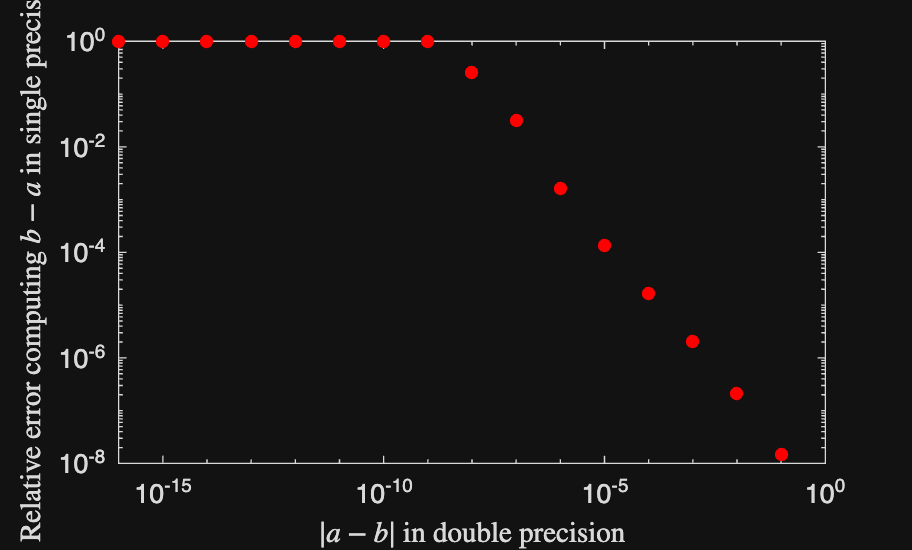


diffs = 10.^(-16:-1);
for i = 1:length(diffs)
    b = a + diffs(i);
    diff_single = single(b) - single(a);
    relerrs(i) = abs(diff_single - diffs(i))/diffs(i);
end
loglog(diffs, relerrs, 'r.', 'MarkerSize', 15);
xlabel('$|a-b|$ in double precision','Interpreter','latex');
ylabel('Relative error computing $b-a$ in single precision','Interpreter','latex');

## Problem 1

### Part (a)

*Forward error analysis of the central difference approximation including truncation and floating-point error.*

Consider the central difference approximation

$D_f = \frac{f(x+h)-f(x-h)}{2h} = f'(x)(1+\delta_t)$, where $\delta_t = O(h^2)$.

Truncation error.

Using Taylor expansions,


$$f(x+h) = f(x)+hf'(x)+\frac{h^2}{2}f''(x)+\frac{h^3}{6}f'''(x)+O(h^4)$$



$$f(x-h) = f(x)-hf'(x)+\frac{h^2}{2}f''(x)-\frac{h^3}{6}f'''(x)+O(h^4)$$


Subtracting,


$$f(x+h)-f(x-h) = 2hf'(x)+\frac{h^3}{3}f'''(x)+O(h^5)$$


and hence

$D_f = f'(x)+\frac{h^2}{6}f'''(x)+O(h^4) = f'(x)(1+\delta_t)$ with $|\delta_t|=O(h^2)$

Floating-point error.

Assuming all arithmetic is performed in floating point, the subtraction step must account for cancellation. Since $f(x+h) \approx f(x-h)$ for small $h$, we model


$$fl(f(x+h)-f(x-h)) = (f(x+h)-f(x-h)) + \delta_s$$


where

$|\delta_s| \le \varepsilon_M (|f(x+h)| + |f(x-h)|)$.

Dividing by $2h$ in floating point gives


$$\hat{D}_f = fl!\left(\frac{fl(f(x+h)-f(x-h))}{2h}\right)$$



$$= \frac{f(x+h)-f(x-h)}{2h} + \frac{\delta_s}{2h} + \delta_d$$


where $|\delta_d| \le \varepsilon_M |D_f|$.

Thus

$\hat{D}_f = D_f + \frac{\delta_s}{2h} + O(\varepsilon_M |D_f|)$.

Using the bound on $\delta_s$,

$\left|\frac{\delta_s}{2h}\right| \le \frac{\varepsilon_M (|f(x+h)| + |f(x-h)|)}{2h}$.

For small $h$, $|f(x+h)|$ and $|f(x-h)|$ are $O(1)$, while the true numerator is $O(h)$. Therefore the dominant rounding contribution behaves like

$\frac{\varepsilon_M}{h}$.

Therefore,

$\hat{D}_f - f'(x) = O(h^2) + O\left(\frac{\varepsilon_M}{h}\right)$.

Absolute error bound.

Applying the triangle inequality,


$$|\hat{D}_f - f'(x)| \le C_1 h^2 + C_2 \frac{\varepsilon_M}{h}$$


for appropriate constants $C_1$ and $C_2$.

Thus,

$|\hat{D}_f-f'(x)| \le A(h^2) + B\left(\frac{\varepsilon_M}{h}\right)$.

If we minimise this relative error by taking the derivative with respect to $h$, we find that,


$$h_{optimal} \propto \epsilon_m^{\frac{1}{3}}$$


And for the case of double presision, we find that this occurs at a value of $6.06\cdot10^{-6}$.

### Part (b)

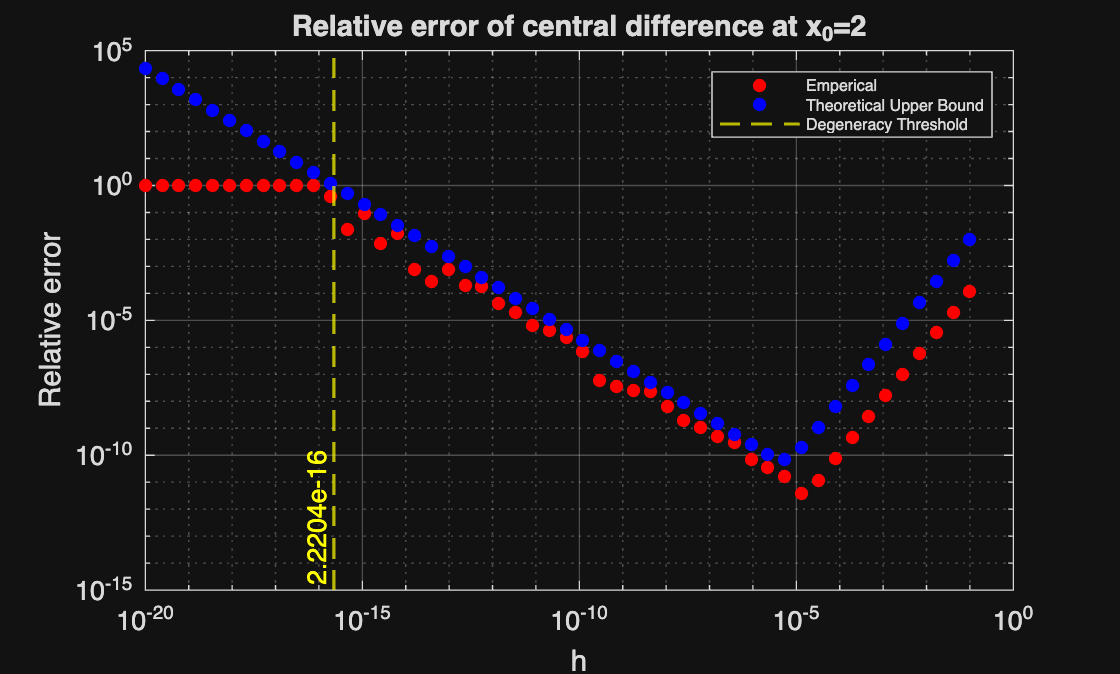

f = @(x) exp(-x) - x*(2-x);  % Define function to take derivative of
x0 = 2;                      % Define point to evaluate at
h = logspace(-1,-20,50);     % Define range of h values to investigate
epsval = eps;                % machine precision for double


%Compute central difference approxiamtion
centdiff = arrayfun(@(hh) (f(x0+hh) - f(x0-hh)) / (2*hh), h);
D_true = 1.86466471676;  %analytically computed value
abs_err = abs(centdiff - D_true); 


%Empirical relative error of central difference scheme
rel_err = abs_err ./ abs(D_true);

%Theoreitcal error bound based on floating point arithmetic model(setting C_1 and C_2 = 1)
error_bound = h.^2 + eps ./ h;

% Plot
figure;
loglog(h, rel_err,'r.', 'MarkerSize', 15);
hold on
loglog(h, error_bound,'b.', 'MarkerSize', 15);
hold on
% Option 1 — modern and simple (R2018b+): xline
xline(eps('double'), '--y', '2.2204e-16', 'LabelHorizontalAlignment','left',...
      'LabelVerticalAlignment','bottom','LineWidth',1.2);
hold off
xlabel('h');
ylabel('Relative error');
title('Relative error of central difference at x_0=2');
lgd = legend('Empirical error','Theoretical bound');
lgd.FontSize = 6;   % default is usually 12
legend('Emperical', 'Theoretical Upper Bound', 'Degeneracy Threshold')
grid on;

One can see, upon inspection of the graph below, there is close aggreement between the theoretical bounds on the error, comprising of the floating point error term $\frac{\epsilon_M}{h}$ and the truncation error term $h^2$. The floating point error term dominates until $h$ is at a value on the order of $10^{-5}$, at which point the quadratic truncation term begins to dominate. The emperical data set exhibits a constant relative error of 1 below the value $h=10^{-16}$, this is the result of a degeneracy in the evaluation of the function $f(x$). For values of $h$ in this interval we have the following degeneracy, $f(x_0+h)=f(x_0)$. This causes the floating point model, $fl(\frac{f(x+h)-f(x-h)}{2h})$, as the numerator certainly vanishes for $h$ in the given threshold. This marks a point of ineficiency between the models upper bound on the relative error, as one can see the theoretical upper bound does not settle on 1 during this interval. In our floating point model, we assumed that the function may be evaluated exactly, this is the root cause of this ineficiency. 

For a more efficient model upper bound, one could define a piecewise function for the relative error, whereby below the value of $h=10^{-16}$, the relative error is set to 1, as the function $f(x)$ cannot discriminate between $x$ and $x\pm h$.

The predicted optimal stepsize size of $h=6.06\cdot10^{-6}$, was seen to be off by less than an order of magnitude when compared with the empirical data, but was inline with the theoretical prediction.

### Part (c)

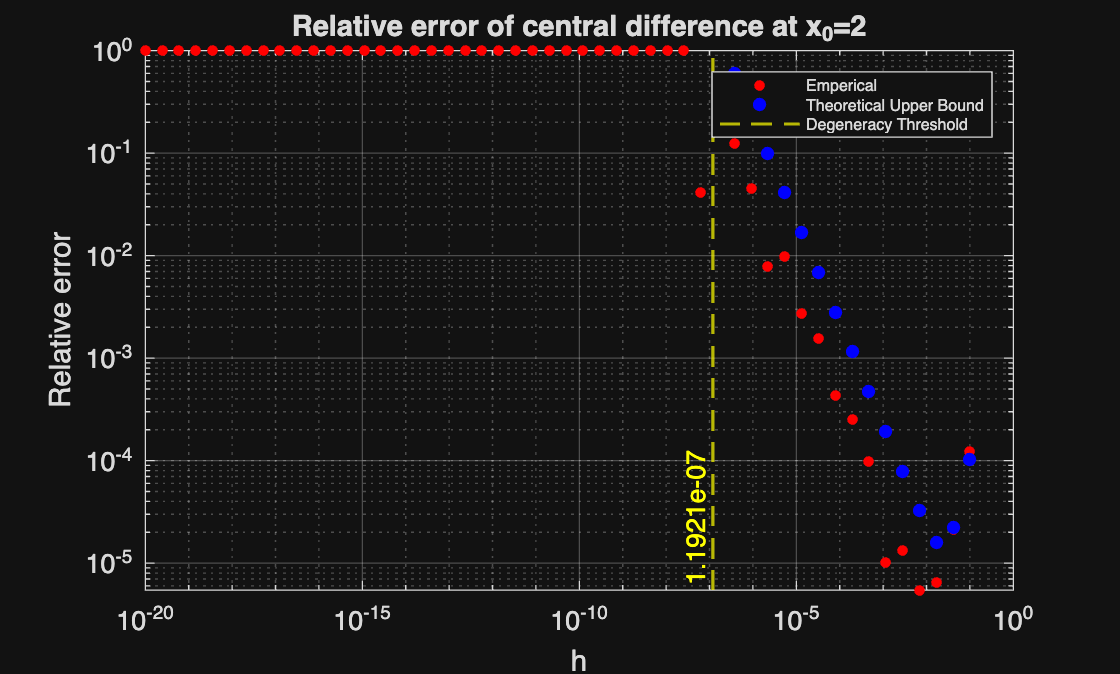

% single-precision central difference and relative error

% Function and true derivative (true value in double)
f = @(x) exp(-x) - x.*(2 - x);   % works for single input
D_true = 1.86466471676;          % double-precision true derivative at x0

% single inputs
x0 = single(2);                       
h = single(logspace(-1, -20, 50));   % h as single

% central difference in single precision (vectorized)
centdiff_single = ( f(x0 + h) - f(x0 - h) ) ./ (2 .* h);  % result is single

% convert results to double for error calculation/plotting
centdiff = double(centdiff_single);
h_double = double(h);

% relative error (use absolute value of true derivative)
abs_err = abs(centdiff - D_true);
rel_err = abs_err ./ abs(D_true);


% changing the error bound constants
error_bound = 0.01.*(h.^2) + 1000000000.*(eps ./ h);

% plot (log-log for clarity)
figure;
loglog(h_double, rel_err, 'r.', 'MarkerSize',12);
hold on
loglog(h, error_bound,'b.', 'MarkerSize', 15);
hold on
% Option 1 — modern and simple (R2018b+): xline
xline(eps('single'), '--y', '1.1921e-07', 'LabelHorizontalAlignment','left',...
      'LabelVerticalAlignment','bottom','LineWidth',1.2);
hold off
xlabel('h');
ylabel('Relative error');
title('Relative error of central difference at x_0=2');
lgd = legend('Empirical error','Theoretical bound');
lgd.FontSize = 6;   % default is usually 12
legend('Emperical', 'Theoretical Upper Bound', 'Degeneracy Threshold')
grid on;
ylim([0 1]);



eps('single')   % ≈ 1.19e-7

ans = single
1.1921e-07

eps('double')   % ≈ 2.22e-16

ans = 2.2204e-16

The structure of the relative error curve is the same when computed in single prescision. 

However, the machine precision in single precision is


$$\varepsilon_M^{(\text{single})} \approx 10^{-7},$$


whereas in double precision it is


$$\varepsilon_M^{(\text{double})} \approx 10^{-16}.$$


As a result:

- The entire error curve is shifted upward.

- The minimum achievable error is significantly larger(on the order of $10^{-5}$ rather than $10^{-11}$).

- The optimal step size, $h_{\text{opt}} \sim \varepsilon_M^{\frac{1}{3}}=4.921\cdot10^{-3}$, occurs at a much larger value in single precision(found by taking derivative of relative error bounds with respect to h,  and setting this to zero).

- The rounding-dominated regime begins at larger values of $h$.

- Degeneracy in the numerator of the central difference scheme occurs when $h$ becomes smaller than the floating-point spacing near $x_0$, which in single precision happens around $10^{-7}$ rather than $10^{-16}$.

One can see that both singgle and double prescision are in line with the theoretical model, and that the accuracy achievable in each method is a function of the value of $\epsilon_m$ in both cases.

## Problem 2

part (a)

The matrix $B$ formed from the basis vectors is


$$B=\left[\begin{array}{cc}\frac{1}{\sqrt{2}}&\frac{1+\gamma}{\sqrt{2+2\gamma+\gamma^2}}\\\frac{1}{\sqrt{2}}&\frac{1}{\sqrt{2+2\gamma+\gamma^2}}\end{array}\right].$$


The $\infty$-norm of a matrix is defined as


$$|A|\infty=\max_i\sum_j |a{ij}|,$$


that is, the maximum absolute row sum.

The row sums of $B$ are


$$r_1=\frac{1}{\sqrt{2}}+\frac{|1+\gamma|}{\sqrt{2+2\gamma+\gamma^2}},$$



$$r_2=\frac{1}{\sqrt{2}}+\frac{1}{\sqrt{2+2\gamma+\gamma^2}}.$$


As $\gamma\to0$, we have $\sqrt{2+2\gamma+\gamma^2}\to\sqrt{2}$, so both $r_1$ and $r_2$ approach $\sqrt{2}$.

Therefore $|B|_\infty$ remains bounded as $\gamma\to0$.

The determinant of $B$ is


$$\det(B)=-\frac{\gamma}{\sqrt{2}\sqrt{2+2\gamma+\gamma^2}}.$$


Hence


$$|\det(B)|=\frac{|\gamma|}{\sqrt{2}\sqrt{2+2\gamma+\gamma^2}}.$$


As $\gamma\to0$, this behaves like $|\det(B)|\sim\frac{|\gamma|}{2}.$

For a $2\times2$ matrix,


$$B^{-1}=\frac{1}{\det(B)}adj(B),$$


so every entry of $B^{-1}$ contains a factor of $1/\det(B)$. Since $\det(B)$ vanishes linearly in $\gamma$, it follows that


$$|B^{-1}|_\infty\sim\frac{C}{|\gamma|}$$


for some constant $C$.

The $\infty$-norm condition number is


$$\kappa_\infty(B)=|B|_\infty|B^{-1}|_\infty.$$


Because $|B|_\infty$* remains bounded while *$|B^{-1}|_\infty$ grows like $1/|\gamma|$, we conclude


$$\kappa_\infty(\gamma)\sim\frac{C}{|\gamma|}\quad\text{as }\gamma\to0.$$


Thus the condition number grows proportionally to $1/|\gamma|$, and the coordinate representation problem becomes increasingly ill-conditioned as $\gamma\to0$.

## Problem 3

Computational graph should be draw on paper and included as part of a PDF.

## Problem 4

load("cont_frac.mat");

Error using load
Unable to find file or directory 'cont_frac.mat'.